# **Computation Vision - Project 2 Report**

**Topic A3:   People and vehicle detection using thermal imagery**

Authors:

- David Marafuz Gaspar - 106541 - david.marafuz.gaspar@tecnico.ulisboa.pt

- Pedro Gaspar Monico - 106626 - pedro.monico@tecnico.ulisboa.pt

Supervisors:

- Prof. Alexandra Moutinho

- Eng. Alexandre Athayde

## 1. Introduction

With the rapid advancement of autonomous driving and Advanced Driver-Assistance Systems (ADAS), the ability to reliably detect pedestrians and vehicles in real-time has become a fundamental requirement for safe road navigation. Traditional RGB-based vision systems, while effective under standard conditions, are inherently limited by their dependence on visible light, making them prone to failure in challenging environments such as darkness, fog, heavy rain, or glare which are precisely the conditions where robust perception is most critical for the safety of both passengers and other road users.

Thermal imaging offers a compelling alternative, as it captures heat signatures emitted naturally by humans and vehicles rather than relying on reflected light. This makes thermal-based detection largely invariant to lighting conditions, providing a more consistent and reliable perception pipeline for safety-critical applications. Unlike RGB cameras, thermal sensors detect temperature differences between objects and their surroundings, preserving the distinct silhouettes of pedestrians and vehicles even in the most adverse scenarios. These properties make thermal sensors an increasingly attractive complement to visible-light cameras in modern ADAS systems.

As part of Topic A3 of the Intelligent Vision Systems course, this project aims to develop and optimize a deep learning-based object detection model using the FLIR ADAS dataset. The goal is to build a system capable of accurately detecting pedestrians and vehicles in real driving scenarios. Specifically, this report details the following steps:

- **Dataset Analysis and Preparation:** Characterization of the FLIR ADAS thermal dataset, identification of relevant object classes, and the structuring of data for training, validation, and testing;

- **Baseline Model:** The design and deployment of an initial object detection pipeline using simple Deep Learning Architecture from what we will improve on;

- **Model Evaluation:** Rigorous training and assessment of the baseline model using standard computer vision metrics to analyze its initial detection capabilities;

- **System Optimization:** Iterative improvement of the detection system through the exploration of advanced architectures, hyperparameter tuning, targeted preprocessing, and data augmentation strategies.

This project explores the development and optimization of a deep learning-based object detection system, demonstrating how careful dataset preparation, model design, and iterative improvement can enhance detection performance, ultimately contributing to safer autonomous navigation.

**Attention**: In order to reduce clutter in the report, auxiliary scripts (specifically those implemented for subsequent processing steps and for plotting purposes) have been organized into separate files and are only referenced in the code when invoked. Auxiliary functions follow the naming convention `aux_<function>.m`, while plotting functions follow `plot_<function>.m`.

## 2. Dataset Analysis and Preparation

### 2.1 Dataset Overview

Before designing and training the object detection architecture, it is essential to understand the underlying data distribution. The FLIR ADAS dataset provides annotations in the standard MS-COCO JSON format [1] and is pre-divided into three dedicated splits: Training, Validation, and Testing. Each split is stored in a separate folder and contains a `coco.json` file with the corresponding image metadata and bounding box annotations. The script below loads each split, parses the COCO annotations, and computes the number of images per split along with their relative proportions. The resulting distribution is summarised in Table 1.

[1] TELEDYNE | FLIR OEM Documentation: [https://oem.flir.com/en-150/solutions/automotive/adas-dataset-form/](https://oem.flir.com/en-150/solutions/automotive/adas-dataset-form/)

%% Define Dataset Paths and Splits
datasetPaths = {'./Data/images_thermal_train', './Data/images_thermal_val', './Data/video_thermal_test'};
splitNames = {'Train', 'Validation', 'Test'};

%% Read Categories from the Training Dataset
cocoPath = fullfile(datasetPaths{1}, 'coco.json');
cocoData = jsondecode(fileread(cocoPath)); 

numClasses = length(cocoData.categories); 
classNames = strings(1, numClasses);
classIDs = zeros(1, numClasses);

for i = 1:numClasses
    classNames(i) = cocoData.categories(i).name;
    classIDs(i) = cocoData.categories(i).id;
end

numImagesPerSplit = zeros(1, length(datasetPaths));
countsPerSplit = zeros(numClasses, length(datasetPaths));

%% Process Each Dataset Split
for d = 1:length(datasetPaths)
    cocoPath = fullfile(datasetPaths{d}, 'coco.json');    
    cocoData = jsondecode(fileread(cocoPath)); 
    
    numImagesPerSplit(d) = length(cocoData.images);
    
    if d == 1
        numImgs   = length(cocoData.images);
        filenames   = cell(numImgs, 1);
        peopleBoxes  = cell(numImgs, 1);
        vehicleBoxes = cell(numImgs, 1);

        imageIDList = zeros(numImgs, 1);
        for k = 1:numImgs
            filenames{k}   = fullfile(datasetPaths{1}, cocoData.images(k).file_name);
            imageIDList(k) = cocoData.images(k).id;
        end
    end

    lowerClassNames = lower(classNames);
    targetClass1 = "person";
    targetClass2 = ["car", "motorcycle", "bus", "train", "truck", "other vehicle"];

    annotations = cocoData.annotations;
    for i = 1:length(annotations)
        if iscell(annotations)
            ann = annotations{i};
        else
            ann = annotations(i);
        end
        
        idx = find(classIDs == ann.category_id);
        if ~isempty(idx)
            countsPerSplit(idx, d) = countsPerSplit(idx, d) + 1;
        end

        % Store bounding boxes for train split visualization
        if d == 1
            catName = lower(classNames(idx));
            imgIdx  = find(imageIDList == ann.image_id, 1);
            bbox    = ann.bbox; % [x, y, w, h]

            if catName == targetClass1
                peopleBoxes{imgIdx} = [peopleBoxes{imgIdx}; bbox];
            elseif any(catName == targetClass2)
                vehicleBoxes{imgIdx} = [vehicleBoxes{imgIdx}; bbox];
            end
        end
    end
end

% Number and Percentage of Images per Split
totalImages = sum(numImagesPerSplit);

pcts = arrayfun(@(x) sprintf('%.2f%%', (x/totalImages)*100), numImagesPerSplit, 'UniformOutput', false);

T_splits = table(splitNames', numImagesPerSplit', pcts', ...
    'VariableNames', {'Split', 'N_Images', 'Percentage'});

disp('Table 1: Image Count and Percentage by Dataset Split');

Table 1: Image Count and Percentage by Dataset Split


disp(T_splits);

        Split         N_Images    Percentage
    ______________    ________    __________

    {'Train'     }     10742      {'68.70%'}
    {'Validation'}      1144      {'7.32%' }
    {'Test'      }      3749      {'23.98%'}



Based on the script's output, the data distribution is:

- Training Set: 10,742 images (68.70%)

- Validation Set: 1,144 images (7.32%)

- Testing Set: 3,749 images (23.98%)

This distribution follows standard deep learning practice, allocating the majority of the data to training while reserving a substantial portion for final evaluation. The test set, comprising approximately 24% of the total data, provides a sufficiently large and unseen sample to produce reliable performance estimates. The validation set, although smaller, is used exclusively during training to monitor generalisation and guide hyperparameter tuning.

### 2.2 Category Analysis

The FLIR ADAS dataset originally contains a large number of annotated categories, however many of these have zero instances across all splits and are therefore disregarded. Table 2 presents only the 16 categories that have at least one annotated instance in the dataset.

% Full Category Table (all classes in dataset)
validIdx = any(countsPerSplit > 0, 2);  % categories with at least 1 instance

T_categories = table(...
    classNames(validIdx)', ...
    classIDs(validIdx)', ...
    countsPerSplit(validIdx, 1), ...
    countsPerSplit(validIdx, 2), ...
    countsPerSplit(validIdx, 3), ...
    'VariableNames', {'Category', 'ID', 'Train', 'Val', 'Test'});

disp('Table 2: All Categories with Non-Zero Instance Counts');

Table 2: All Categories with Non-Zero Instance Counts


disp(T_categories);

       Category        ID    Train    Val     Test 
    _______________    __    _____    ____    _____

    "person"            1    50478    4470    12323
    "bike"              2     7237     170      113
    "car"               3    73623    7133    30517
    "motor"             4     1116      55     3314
    "bus"               6     2245     179        0
    "train"             7        5       0        0
    "truck"             8      829      46     2634
    "light"            10    16198    2005     6758
    "hydrant"          11     1095      94      277
    "sign"             12    20770    2472     5660
    "dog"              17        4       0       25
    "deer"             18        8       0        0
    "skateboard"       37       29       3        0
    "stroller"         73       15       6       

As shown in Table 2, the dataset includes 16 active categories: Person, Bike, Car, Motor, Bus, Train, Truck, Light, Hydrant, Sign, Dog, Deer, Skateboard, Stroller, Scooter, and Other Vehicle. A clear class imbalance is visible since the classes Person and Car dominate across all splits, while categories such as Train, Dog, Deer, Skateboard, Stroller, and Scooter have very few instances, particularly in the validation and test sets.

In line with the objectives of Topic A3, which focuses on detecting pedestrians and vehicles in real driving scenarios, the dataset is filtered to retain only the 7 most relevant categories: Person, Car, Motorcycle, Bus, Train, Truck, and Other Vehicle. Categories unrelated to road safety such as Traffic Light, Fire Hydrant, Street Sign, and animals are excluded from the detection pipeline.

### 2.3 Target Class Selection

As evidenced by Table 2, the dataset exhibits a significant class imbalance. Person and Car account for the vast majority of annotated instances, while categories such as Train, Motorcycle, and Other Vehicle are considerably underrepresented. Training a multi-class detector on this raw distribution would likely result in a model biased towards the dominant classes, with poor generalisation on the minority ones.

To address this, the detection task is reformulated into two well-balanced and semantically meaningful classes:

- Class 1 **(People):** directly mapped from the Person category, representing all pedestrians in the scene.

- Class 2 **(Vehicles):** formed by merging Car, Motorcycle, Bus, Train, Truck, and Other Vehicle into a single class. This grouping is justified by the shared detection objective for identifying any road vehicle ensuring that the combined class has sufficient training examples for reliable detection.

The instance counts for the selected categories are presented in Table 3. This grouping strategy ensures the model focuses on the objects most critical to road safety, while mitigating the effects of class imbalance through category consolidation.

% Define target categories and display instance counts
targetCategories = ["person", "car", "motor", "bus", "train", "truck", "other vehicle"];

catLabels  = strings(length(targetCategories), 1);
trainCounts = zeros(length(targetCategories), 1);
valCounts   = zeros(length(targetCategories), 1);
testCounts  = zeros(length(targetCategories), 1);

for c = 1:length(targetCategories)
    idxCat = find(lowerClassNames == targetCategories(c));
    if ~isempty(idxCat)
        catLabels(c)   = classNames(idxCat);
        trainCounts(c) = countsPerSplit(idxCat, 1);
        valCounts(c)   = countsPerSplit(idxCat, 2);
        testCounts(c)  = countsPerSplit(idxCat, 3);
    end
end

T_target = table(catLabels, trainCounts, valCounts, testCounts, ...
    'VariableNames', {'Category', 'Train', 'Val', 'Test'});

disp('Table 3: Instance Counts for Target Categories');

Table 3: Instance Counts for Target Categories


disp(T_target);

       Category        Train    Val     Test 
    _______________    _____    ____    _____

    "person"           50478    4470    12323
    "car"              73623    7133    30517
    "motor"             1116      55     3314
    "bus"               2245     179        0
    "train"                5       0        0
    "truck"              829      46     2634
    "other vehicle"     1373      63      696



### 2.4 Data Preparation

While the full FLIR ADAS dataset provides over 14,000 training images, training on the complete dataset imposes significant computational demands in terms of memory, processing time, and GPU requirements. Given the hardware constraints typical of an academic setting, and in the interest of rapid iteration during model development and hyperparameter tuning, a representative 10% subset was sampled from each split.

This decision is supported by several practical arguments. First, the dataset is heavily dominated by two classes (Person and Vehicle), meaning that even a 5% sample retains a statistically representative distribution of instances across classes. Second, reducing the dataset size allows for faster training cycles, making it feasible to experiment with different architectures, augmentation strategies, and training parameters within a reasonable timeframe. Third, it is standard practice in deep learning research to validate a pipeline on a smaller subset before scaling up, as it helps identify implementation errors and convergence issues early without incurring the full computational cost.

The subsampling is performed by the auxiliary function `aux_subsampleDataset.m`, which randomly samples a specified fraction of images from each split while preserving the original folder structure and COCO annotation format. The resulting subsets are saved to new folders suffixed with `_subset`.

subsetFraction = 0.05;   % 10% of each split
rngSeed        = 42;     % for reproducibility

splitPaths = {
    './Data/images_thermal_train',
    './Data/images_thermal_val',
    './Data/video_thermal_test'
};

subsetPaths = cell(size(splitPaths));
for d = 1:numel(splitPaths)
    subsetPaths{d} = aux_subsampleDataset(splitPaths{d}, subsetFraction, rngSeed);
    fprintf('Subset created: %s\n', subsetPaths{d});
end

   Copied 0 / 537 images
   [./Data/images_thermal_train] 10742 → 537 images (5%) saved to ./Data/images_thermal_train_subset


Subset created: ./Data/images_thermal_train_subset


   Copied 0 / 57 images
   [./Data/images_thermal_val] 1144 → 57 images (5%) saved to ./Data/images_thermal_val_subset


Subset created: ./Data/images_thermal_val_subset


   Copied 0 / 187 images
   [./Data/video_thermal_test] 3749 → 187 images (5%) saved to ./Data/video_thermal_test_subset


Subset created: ./Data/video_thermal_test_subset



% Stats table
splitLabels  = {'Train'; 'Validation'; 'Test'};
fullCounts   = numImagesPerSplit';
subsetCounts = zeros(3,1);
for d = 1:3
    subCocoPath = fullfile(subsetPaths{d}, 'coco.json');
    subCoco     = jsondecode(fileread(subCocoPath));
    subsetCounts(d) = numel(subCoco.images);
end
retained = arrayfun(@(a,b) sprintf('%.1f%%', 100*a/b), ...
                    subsetCounts, fullCounts, 'UniformOutput', false);

T_subset = table(splitLabels, fullCounts, subsetCounts, retained, ...
    'VariableNames', {'Split','Full_Dataset','Subset','Retained'});

disp('Table 4: Full Dataset vs. Subset Size per Split');

Table 4: Full Dataset vs. Subset Size per Split


disp(T_subset);

        Split         Full_Dataset    Subset    Retained
    ______________    ____________    ______    ________

    {'Train'     }       10742         537      {'5.0%'}
    {'Validation'}        1144          57      {'5.0%'}
    {'Test'      }        3749         187      {'5.0%'}



To better understand the dataset imagery, the plotted examples demonstrate that the scale, aspect ratio, and visual density of the bounding boxes vary significantly depending on the environment. The figure illustrates two representative scenarios: a road segment containing two vehicles, and an instance featuring a single vehicle alongside a pedestrian.

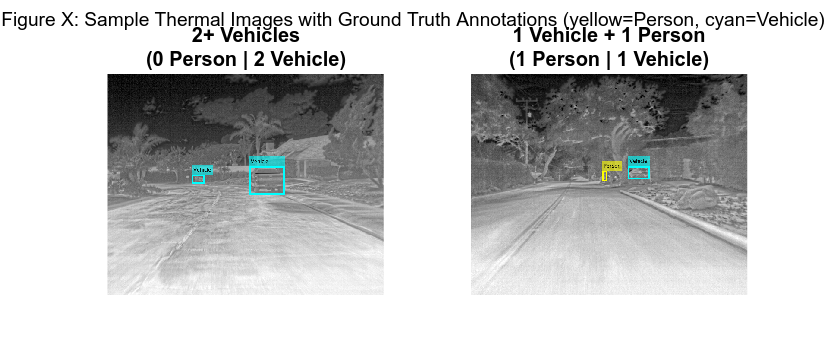

% Load subset training annotations
subCocoPath = fullfile(subsetPaths{1}, 'coco.json');
subCoco     = jsondecode(fileread(subCocoPath));

% Build image_id → annotations map
annByImage = containers.Map('KeyType','double','ValueType','any');
for k = 1:numel(subCoco.annotations)
    if iscell(subCoco.annotations); ann = subCoco.annotations{k};
    else;                           ann = subCoco.annotations(k); end
    id = double(ann.image_id);
    if ~isKey(annByImage, id); annByImage(id) = {}; end
    annByImage(id) = [annByImage(id), {ann}];
end

% Build category_id → label string
catLabels = containers.Map('KeyType','double','ValueType','char');
for i = 1:numel(subCoco.categories)
    if iscell(subCoco.categories); cat = subCoco.categories{i};
    else;                          cat = subCoco.categories(i); end
    name = lower(cat.name);
    if strcmp(name, 'person')
        catLabels(double(cat.id)) = 'Person';
    elseif any(strcmp(name, ["car","motor","bus","train","truck","other vehicle"]))
        catLabels(double(cat.id)) = 'Vehicle';
    else
        catLabels(double(cat.id)) = cat.name;
    end
end

% Find images matching specific criteria
% Slot 1: 2+ vehicles
% Slot 2: exactly 1 vehicle, 1 person

slot = cell(2, 1);   

for i = 1:numel(subCoco.images)
    if iscell(subCoco.images); imgInfo = subCoco.images{i};
    else;                      imgInfo = subCoco.images(i); end

    % Make sure you have your external function loadAnnotatedImage.m in the folder!
    [img, labels, bboxes] = aux_load_annotaded_image(imgInfo, subsetPaths{1}, annByImage, catLabels);
    if isempty(img) || isempty(bboxes); continue; end

    nPerson  = sum(strcmp(labels, 'Person'));
    nVehicle = sum(strcmp(labels, 'Vehicle'));

    % Slot 1 — 2+ vehicles
    if isempty(slot{1}) && nVehicle >= 2
        slot{1} = {img, labels, bboxes}; continue;
    end
    % Slot 2 — exactly 1 vehicle + 1 person
    if isempty(slot{2}) && nVehicle == 1 && nPerson == 1
        slot{2} = {img, labels, bboxes}; continue;
    end

    % Stop once both slots are filled
    if ~any(cellfun(@isempty, slot)); break; end
end

% Plot side-by-side (1x2 grid)
titles = {
    '2+ Vehicles',
    '1 Vehicle + 1 Person'
};

% Made the window wider (1200) and shorter (500) for a side-by-side view
figure('Name', 'Sample Ground Truth', 'Position', [100 100 1200 500]);

for s = 1:2
    if isempty(slot{s})
        fprintf('   Warning: no image found for slot %d\n', s);
        continue;
    end

    img    = slot{s}{1};
    labels = slot{s}{2};
    bboxes = slot{s}{3};

    for j = 1:size(bboxes, 1)
        color = 'yellow';
        if strcmp(labels{j}, 'Vehicle'); color = 'cyan'; end
        % Bumped LineWidth to 4 for bolder/bigger boxes
        img = insertObjectAnnotation(img, 'rectangle', bboxes(j,:), ...
            labels{j}, 'Color', color, 'LineWidth', 4, 'FontSize', 12);
    end

    nP = sum(strcmp(labels, 'Person'));
    nV = sum(strcmp(labels, 'Vehicle'));

    % 1 row, 2 columns, position s
    subplot(1, 2, s); 
    imshow(img);
    title(sprintf('%s\n(%d Person | %d Vehicle)', titles{s}, nP, nV), 'FontSize', 12);
end

sgtitle('Figure X: Sample Thermal Images with Ground Truth Annotations (yellow=Person, cyan=Vehicle)');

Visualizing these ground truth annotations highlights the inherent complexities of the data, particularly regarding the sizes of the target objects. As demonstrated in the second sample of Figure X, the bounding boxes for objects can be exceedingly small, illustrating how scale varies significantly based on distance from the camera. Identifying these challenges early on is essential for designing an effective object detection pipeline.

## 3. Object Detection Architectures

### 3.1. Baseline Machine Learning: HOG + SVM 

### 3.2. Baseline Deep Learning: YOLOv2 + Transfer Learning 

To overcome the spatial and contextual limitations of the classical machine learning approach, a baseline deep learning model was implemented. Following the guidelines for Topic A3 , the objective is to detect pedestrians and vehicles within the FLIR ADAS dataset. A You Only Look Once (YOLOv2) architecture was selected, utilizing transfer learning to accelerate the training process and improve feature extraction.

### 3.3. Optimized Deep Learning: Augmentation & Fine-Tuning 